clear all
close all
clc

% === Select all required user data for preprocessing and Analysis
[user_path, base_path, func_nii, t1_nii, t1_nii2, ho_gz, json_path] = select_all_data()

user_path = 'D:\UniGE\Research_Track\ds000224-download\sub-MSC03'

base_path = 'D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces'

func_nii = 'D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\sub-MSC03_ses-func01_task-memoryfaces_bold.nii.gz'

t1_nii = 'D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-struct01\anat\sub-MSC03_ses-struct01_run-01_T1w.nii.gz'

t1_nii2 = 'D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-struct01\anat\sub-MSC03_ses-struct01_run-02_T1w.nii.gz'

ho_gz = 'D:\UniGE\Research_Track\ds000224-download\Harvard Oxford Atlas\HarvardOxford-cort-maxprob-thr25-2mm.nii.gz'

json_path = 'D:\UniGE\Research_Track\ds000224-download\JSON BIDS\task-memoryfaces_bold.json'


% === Manifest (auto: lives next to the functional you selected)
function save_manifest_to(manifest_path, M)
    save(manifest_path, 'M');
end

manifest_path = fullfile(fileparts(func_nii), 'manifest.mat');

M = struct();                                 % will store paths from each step
if isfile(manifest_path)                      % load previous outputs if available
    S = load(manifest_path);
    if isfield(S,'M'), M = S.M; end
end
save_manifest = @() save(manifest_path, 'M'); % tiny saver

% === Where to save figures ===
fig_dir = fullfile(fileparts(func_nii), 'figures');
if ~exist(fig_dir, 'dir'); mkdir(fig_dir); end


% === Make sure selected files are unzipped (.nii not .nii.gz) ===
% Functional EPI
if endsWith(func_nii, '.gz')
    fprintf('Unzipping %s ...\n', func_nii);
    gunzip(func_nii);               % creates the .nii next to it
    func_nii = erase(func_nii, '.gz');  % update path to the new .nii
end

Unzipping D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\sub-MSC03_ses-func01_task-memoryfaces_bold.nii.gz ...



% T1 run-01
if endsWith(t1_nii, '.gz')
    fprintf('Unzipping %s ...\n', t1_nii);
    gunzip(t1_nii);
    t1_nii = erase(t1_nii, '.gz');
end

Unzipping D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-struct01\anat\sub-MSC03_ses-struct01_run-01_T1w.nii.gz ...



% T1 run-02
if endsWith(t1_nii2, '.gz')
    fprintf('Unzipping %s ...\n', t1_nii2);
    gunzip(t1_nii2);
    t1_nii2 = erase(t1_nii2, '.gz');
end

Unzipping D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-struct01\anat\sub-MSC03_ses-struct01_run-02_T1w.nii.gz ...



% Harvard–Oxford atlas
if endsWith(ho_gz, '.gz')
    fprintf('Unzipping %s ...\n', ho_gz);
    gunzip(ho_gz);
    ho_gz = erase(ho_gz, '.gz');    % reuse same variable name with the .nii path
end

Unzipping D:\UniGE\Research_Track\ds000224-download\Harvard Oxford Atlas\HarvardOxford-cort-maxprob-thr25-2mm.nii.gz ...


Step 1: computing preprocessing...




------------------------------------------------------------------------
21-Oct-2025 10:43:49 - Running job #1
------------------------------------------------------------------------
21-Oct-2025 10:43:49 - Running 'Slice Timing'

SPM25: spm_slice_timing                            10:43:50 - 21/10/2025
Number of slices is...                  :                             36
Time to Repeat (TR) is...               :                            2.2
Parameters are specified as...          :                  slice indices
Completed                               :          10:45:56 - 21/10/2025
21-Oct-2025 10:45:56 - Done    'Slice Timing'
21-Oct-2025 10:45:56 - Done



------------------------------------------------------------------------
21-Oct-2025 10:46:00 - Running job #1
------------------------------------------------------------------------
21-Oct-2025 10:46:00 - Running 'Realign: Estimate & Reslice'

SPM25:

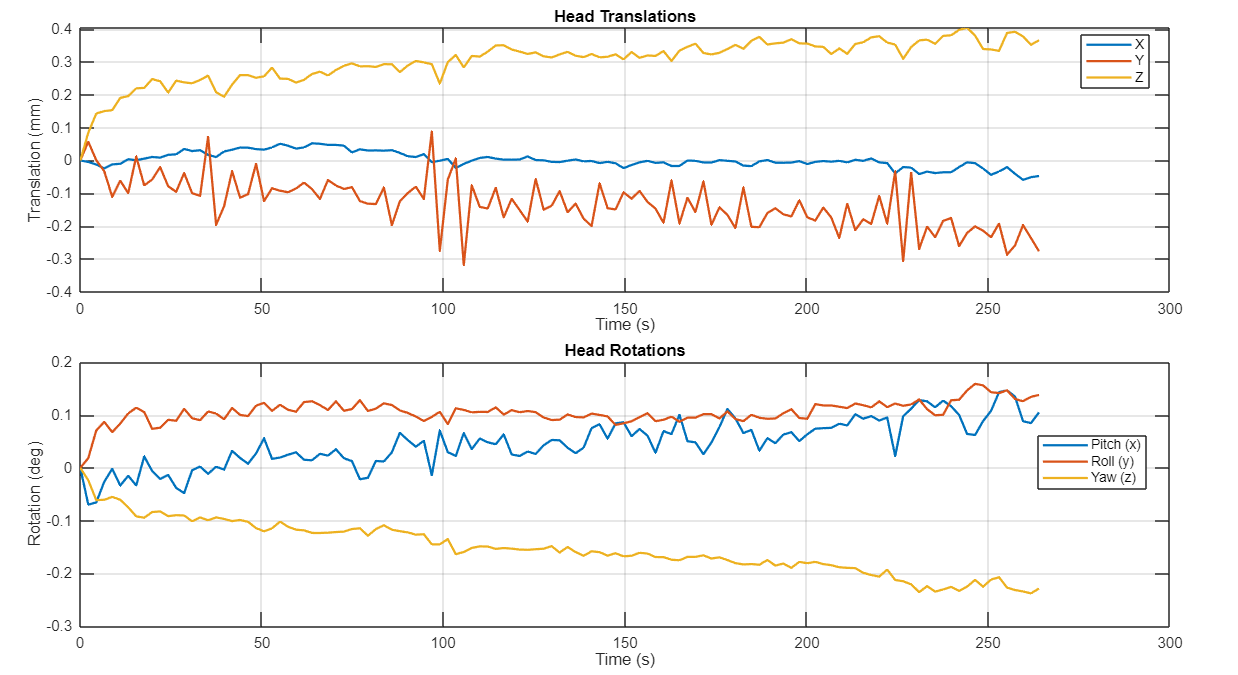

Saved: D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step1_motion_params'.png


% === Step 1: Preprocess Functional (reuse if available)
if isfield(M,'realigned_path') && isfile(M.realigned_path) && ...
   isfield(M,'mean_epi_path')  && isfile(M.mean_epi_path)
    fprintf('Step 1: using cached outputs (QC-only)...\n');

    % pull TR & rp_path from manifest; fallback if missing
    if isfield(M,'TR'),      TR = M.TR;      end
    if isfield(M,'rp_path'), rp_path = M.rp_path; end

    if ~exist('TR','var') || isempty(TR)
        fid = fopen(json_path); raw = fread(fid, inf); str = char(raw'); fclose(fid);
        meta = jsondecode(str);  TR = meta.RepetitionTime;
    end
    if ~exist('rp_path','var') || isempty(rp_path) || ~isfile(rp_path)
        [out_dir, ra_name, ~] = fileparts(M.realigned_path);
        base_a = ra_name;
        if startsWith(ra_name,'ra'), base_a = ra_name(2:end);
        elseif startsWith(ra_name,'r'), base_a = ['a' ra_name(2:end)];
        elseif ~startsWith(ra_name,'a'), base_a = ['a' ra_name];
        end
        rp_path = fullfile(out_dir, ['rp_' base_a '.txt']);
    end

    % --- QC-only: regenerate plots from cached outputs ---
    preprocess_functional(func_nii, json_path, ...
        'QCOnly', true, ...
        'CachedRealignedPath', M.realigned_path, ...
        'SaveFigures', true, ...
        'SaveDir', fig_dir, ...
        'FigurePrefix', 'step1_');

else
    fprintf('Step 1: computing preprocessing...\n');
    [realigned_path, mean_epi_path, rp_path] = preprocess_functional(func_nii, json_path, ...
        'SaveFigures', true, 'SaveDir', fig_dir, 'FigurePrefix', 'step1_');

    % cache outputs
    fid = fopen(json_path); raw = fread(fid, inf); str = char(raw'); fclose(fid);
    meta = jsondecode(str);  TR = meta.RepetitionTime;
    M.realigned_path = realigned_path;
    M.mean_epi_path  = mean_epi_path;
    M.rp_path        = rp_path;
    M.TR             = TR;
    save_manifest_to(manifest_path, M);
end

Step 2: computing skull-strip outputs…


Item 'Warping Regularisation', field 'val': Size mismatch (required [1  5], present [1  1]).


------------------------------------------------------------------------
21-Oct-2025 10:48:38 - Running job #1
------------------------------------------------------------------------
21-Oct-2025 10:48:38 - Running 'Segment'

SPM25: spm_preproc_run                             10:48:38 - 21/10/2025
Segment D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-struct01\anat\sub-MSC03_ses-struct01_run-01_T1w.nii,1
Completed                               :          10:56:23 - 21/10/2025
21-Oct-2025 10:56:23 - Done    'Segment'
21-Oct-2025 10:56:24 - Done

Item 'Warping Regularisation', field 'val': Size mismatch (required [1  5], present [1  1]).


----------------------

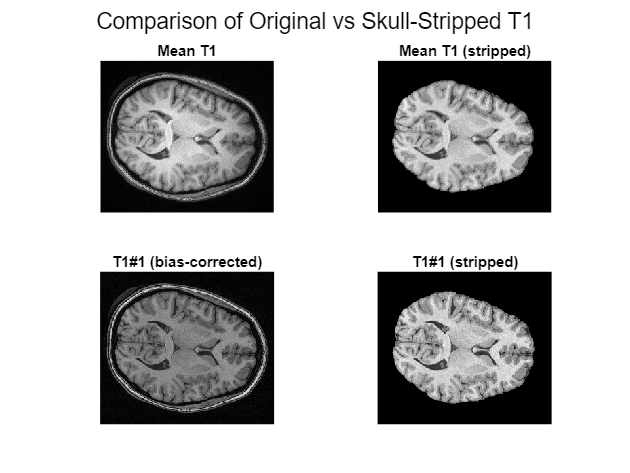

Saved in:
  D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step2_T1_comparison.png
  D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step2_T1_comparison.fig


% === Step 2: Skull-strip T1 (auto: compute first run, reuse thereafter)
outdir      = fileparts(t1_nii);
cache_mean  = fullfile(outdir,'mean_T1_stripped.nii');
cache_mask  = fullfile(outdir,'brain_mask_meanT1.nii');

if isfile(cache_mean) && isfile(cache_mask)
    fprintf('Step 2:  using cached outputs (QC-only)..\n');
    % QC-only from cached products (no recomputation)
    skullstrip_T1(t1_nii, t1_nii2, ...
        'QCOnly', true, 'SaveFigures', true, ...
        'SaveDir', fig_dir, 'FigurePrefix', 'step2_');
    mean_t1_stripped = cache_mean;
    brain_mask_path  = cache_mask;
else
    fprintf('Step 2: computing skull-strip outputs…\n');
    [mean_t1_stripped, brain_mask_path] = skullstrip_T1(t1_nii, t1_nii2, ...
        'SaveFigures', true, 'SaveDir', fig_dir, 'FigurePrefix', 'step2_');
end


% keep manifest in sync
M.mean_t1_stripped = mean_t1_stripped;
M.brain_mask_path  = brain_mask_path;
save_manifest_to(manifest_path, M);



% === Step 3: FAST rigid coregistration of EPI to T1

realigned_path = coreg_epi_to_t1_estimate(mean_t1_stripped, mean_epi_path, realigned_path);



------------------------------------------------------------------------
21-Oct-2025 11:02:14 - Running job #1
------------------------------------------------------------------------
21-Oct-2025 11:02:14 - Running 'Coregister: Estimate'

SPM25: spm_coreg                                   11:02:15 - 21/10/2025
Completed                               :          11:02:29 - 21/10/2025
21-Oct-2025 11:02:48 - Done    'Coregister: Estimate'
21-Oct-2025 11:02:48 - Done



% === Step 4: Reslice T1 mask to mean EPI grid (Nearest Neighbor)
if isfield(M,'resliced_mask_path') && isfile(M.resliced_mask_path) && ...
   isfield(M,'mask_src') && strcmp(M.mask_src, brain_mask_path) && ...
   isfield(M,'mask_ref') && strcmp(M.mask_ref, mean_epi_path)

    fprintf('Step 4: using cached outputs.\n');
    resliced_mask_path = M.resliced_mask_path;

else
    resliced_mask_path = reslice_t1mask_to_epi(mean_epi_path, brain_mask_path);

    % persist cache info
    M.resliced_mask_path = resliced_mask_path;
    M.mask_src = brain_mask_path;   % source (T1-space) mask used
    M.mask_ref = mean_epi_path;     % reference (mean EPI) used
    save_manifest_to(manifest_path, M);
end



------------------------------------------------------------------------
21-Oct-2025 11:06:14 - Running job #1
------------------------------------------------------------------------
21-Oct-2025 11:06:14 - Running 'Coregister: Reslice'

SPM25: spm_reslice                                 11:06:14 - 21/10/2025
Completed                               :          11:06:15 - 21/10/2025
21-Oct-2025 11:06:15 - Done    'Coregister: Reslice'
21-Oct-2025 11:06:15 - Done



Step 5: computing EPI skull-strip…




------------------------------------------------------------------------
21-Oct-2025 11:06:38 - Running job #1
------------------------------------------------------------------------
21-Oct-2025 11:06:38 - Running 'Coregister: Reslice'

SPM25: spm_reslice                                 11:06:38 - 21/10/2025
Completed                               :          11:06:44 - 21/10/2025
21-Oct-2025 11:06:44 - Done    'Coregister: Reslice'
21-Oct-2025 11:06:44 - Done



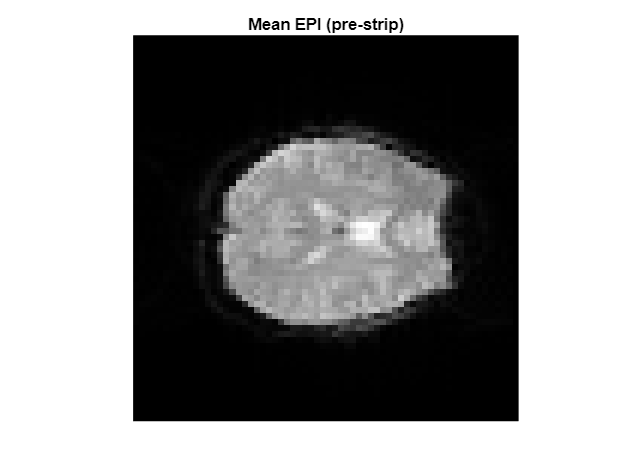

Saved (Pre-strip) in:
  D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step5_mean_epi_pre_strip.png
  D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step5_mean_epi_pre_strip.fig


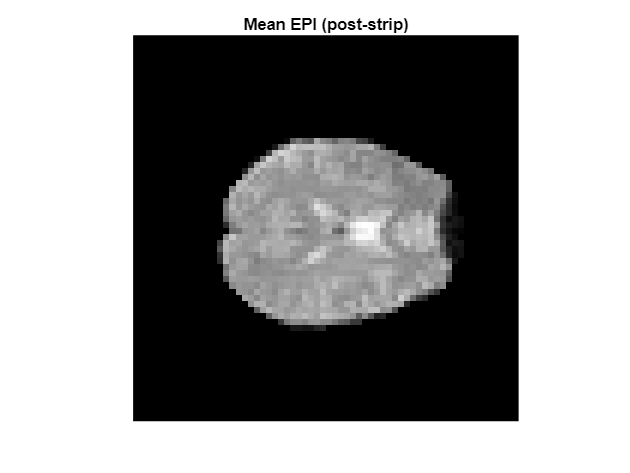

Saved (Post-strip) in:
  D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step5_mean_epi_post_strip.png
  D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step5_mean_epi_post_strip.fig


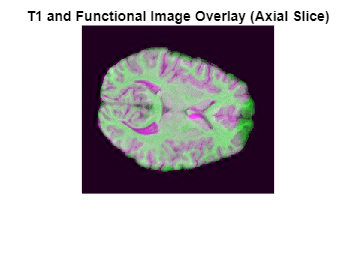

Saved Overlay in:
  D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step5_overlay.png
  D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step5_overlay.fig


% === Step 5: Skull-strip Functional (reuse if available)
have_cache = isfield(M,'mean_epi_stripped_path') && isfile(M.mean_epi_stripped_path) && ...
             isfield(M,'epi_stripped_path')      && isfile(M.epi_stripped_path);

if have_cache
    fprintf(' Step 5: using cached outputs (QC-only)..\n');
    skullstrip_epi(realigned_path, resliced_mask_path, mean_t1_stripped, ...
        'SaveFigures', true, 'SaveDir', fig_dir, 'QCOnly', true);
    mean_epi_stripped_path = M.mean_epi_stripped_path;
    epi_stripped_path      = M.epi_stripped_path;
else
    fprintf('Step 5: computing EPI skull-strip…\n');
    [mean_epi_stripped_path, epi_stripped_path] = skullstrip_epi( ...
        realigned_path, resliced_mask_path, mean_t1_stripped, ...
        'SaveFigures', true, 'SaveDir', fig_dir);
    M.mean_epi_stripped_path = mean_epi_stripped_path;
    M.epi_stripped_path      = epi_stripped_path;
    save_manifest_to(manifest_path, M);
end

% === Step 6: Normalize T1 to MNI (reuse if available)
if isfield(M,'y_field_path') && isfile(M.y_field_path) && ...
   isfield(M,'iy_field_path')&& isfile(M.iy_field_path)
    fprintf('Step 6: using cached outputs.\n');
    y_field_path  = M.y_field_path;
    iy_field_path = M.iy_field_path;
else
    [y_field_path, iy_field_path] = normalize_T1_to_mni(mean_t1_stripped);
    M.y_field_path  = y_field_path;
    M.iy_field_path = iy_field_path;
    save_manifest_to(manifest_path, M);
end

Item 'Warping Regularisation', field 'val': Size mismatch (required [1  5], present [1  1]).


------------------------------------------------------------------------
21-Oct-2025 11:09:48 - Running job #1
------------------------------------------------------------------------
21-Oct-2025 11:09:48 - Running 'Segment'

SPM25: spm_preproc_run                             11:09:48 - 21/10/2025
Segment D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-struct01\anat\mean_T1_stripped.nii,1
Completed                               :          11:18:54 - 21/10/2025
21-Oct-2025 11:18:54 - Done    'Segment'
21-Oct-2025 11:18:55 - Done



% === Step 7: Warp EPI to MNI space (2mm), warp+reslice T1 onto wEPI grid

if isfield(M,'warped_epi_path') && isfile(M.warped_epi_path) && ...
   isfield(M,'rT1_on_wEPIz')     && isfile(M.rT1_on_wEPI)
    fprintf('Step 7: using cached outputs.\n');
    warped_epi_path  = M.warped_epi_path;
    rT1_on_wEPI      = M.rT1_on_wEPI;
else

    [warped_epi_path, rT1_on_wEPI] = warp_epi_to_mni(epi_stripped_path, mean_t1_stripped, y_field_path);
    M.warped_epi_path = warped_epi_path;
    M.rT1_on_wEPI     = rT1_on_wEPI;
    save_manifest_to(manifest_path, M);
end



------------------------------------------------------------------------
21-Oct-2025 11:23:47 - Running job #1
------------------------------------------------------------------------
21-Oct-2025 11:23:47 - Running 'Normalise: Write'
21-Oct-2025 11:26:55 - Done    'Normalise: Write'
21-Oct-2025 11:26:55 - Done



------------------------------------------------------------------------
21-Oct-2025 11:26:58 - Running job #1
------------------------------------------------------------------------
21-Oct-2025 11:26:58 - Running 'Normalise: Write'
21-Oct-2025 11:27:04 - Done    'Normalise: Write'
21-Oct-2025 11:27:04 - Done



------------------------------------------------------------------------
21-Oct-2025 11:27:07 - Running job #1
------------------------------------------------------------------------
21-Oct-2025 11:27:07 - Running 'Coregister: Reslice'

SPM25: spm_reslice                                 11:27:07 - 21/10/2025

% === Step 8: Reslice HO to wEPI space (reuse if available)
if isfield(M,'ho_resliced_path') && isfile(M.ho_resliced_path)
    fprintf('Step 8: using cached outputs.\n');
    ho_resliced_path = M.ho_resliced_path;
else
    ho_resliced_path = project_HO_to_epi(warped_epi_path, ho_gz);
    M.ho_resliced_path = ho_resliced_path;
    save_manifest_to(manifest_path, M);
end



------------------------------------------------------------------------
21-Oct-2025 11:40:21 - Running job #1
------------------------------------------------------------------------
21-Oct-2025 11:40:21 - Running 'Coregister: Reslice'

SPM25: spm_reslice                                 11:40:21 - 21/10/2025
Completed                               :          11:40:21 - 21/10/2025
21-Oct-2025 11:40:21 - Done    'Coregister: Reslice'
21-Oct-2025 11:40:21 - Done





fprintf('\n Preprocessing complete. Data is aligned and parcellated. Ready for analysis.\n');


 Preprocessing complete. Data is aligned and parcellated. Ready for analysis.


Func data size:
    79    95    79   121

Atlas data size:
    79    95    79



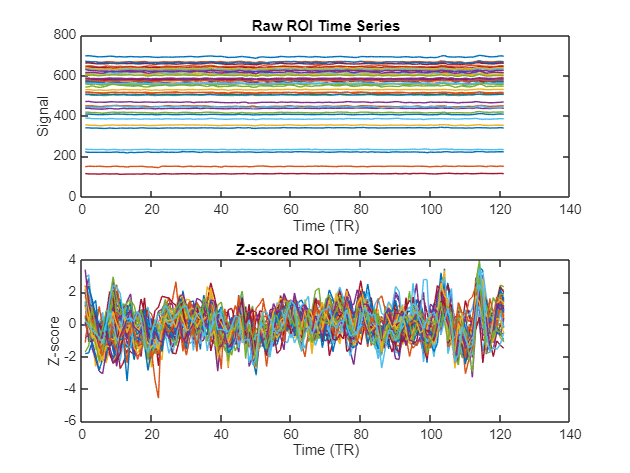

Raw ROI Timeseries Saved in : D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step9_roi_timeseries_overview.png
          D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step9_roi_timeseries_overview.fig


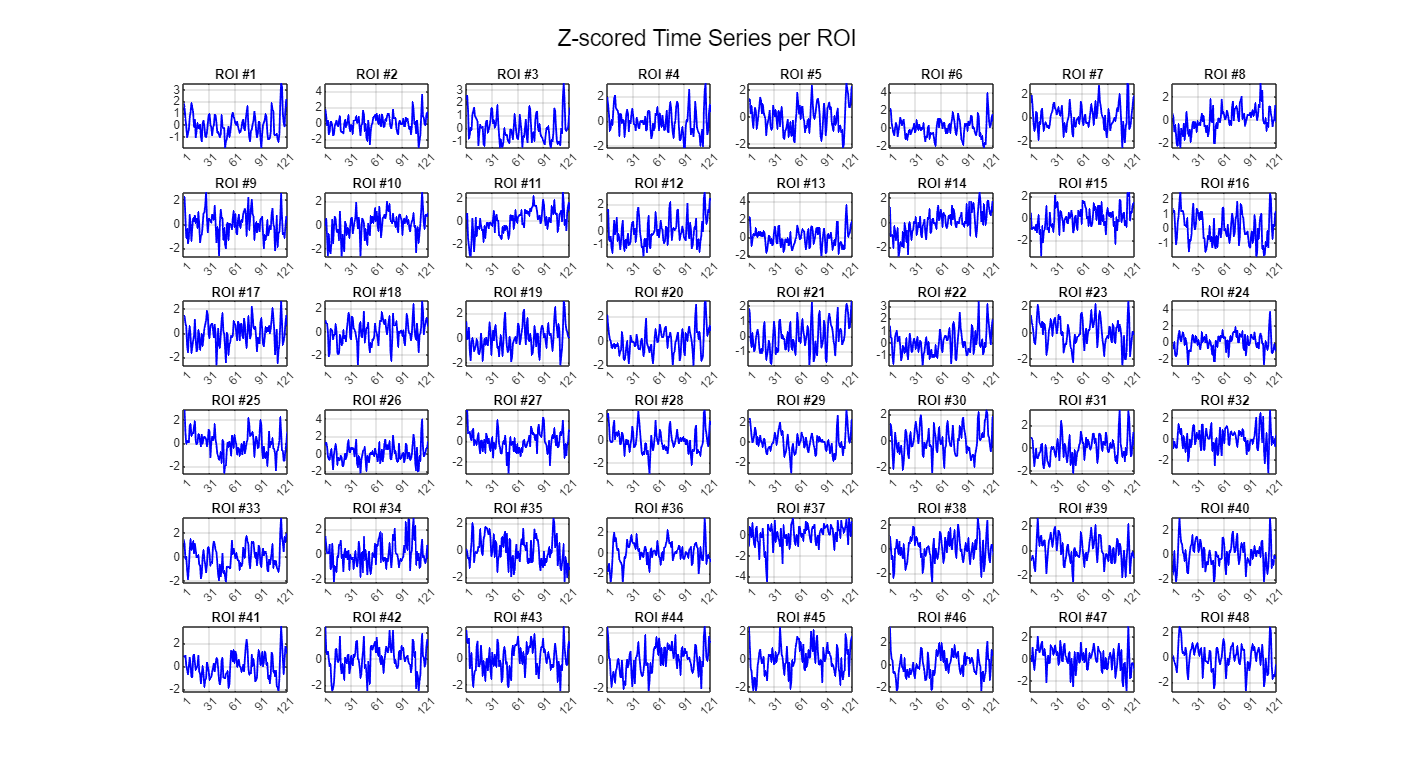

Z-Scored Timeseries Saved in: D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step9_roi_timeseries_z_byROI.png
          D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step9_roi_timeseries_z_byROI.fig


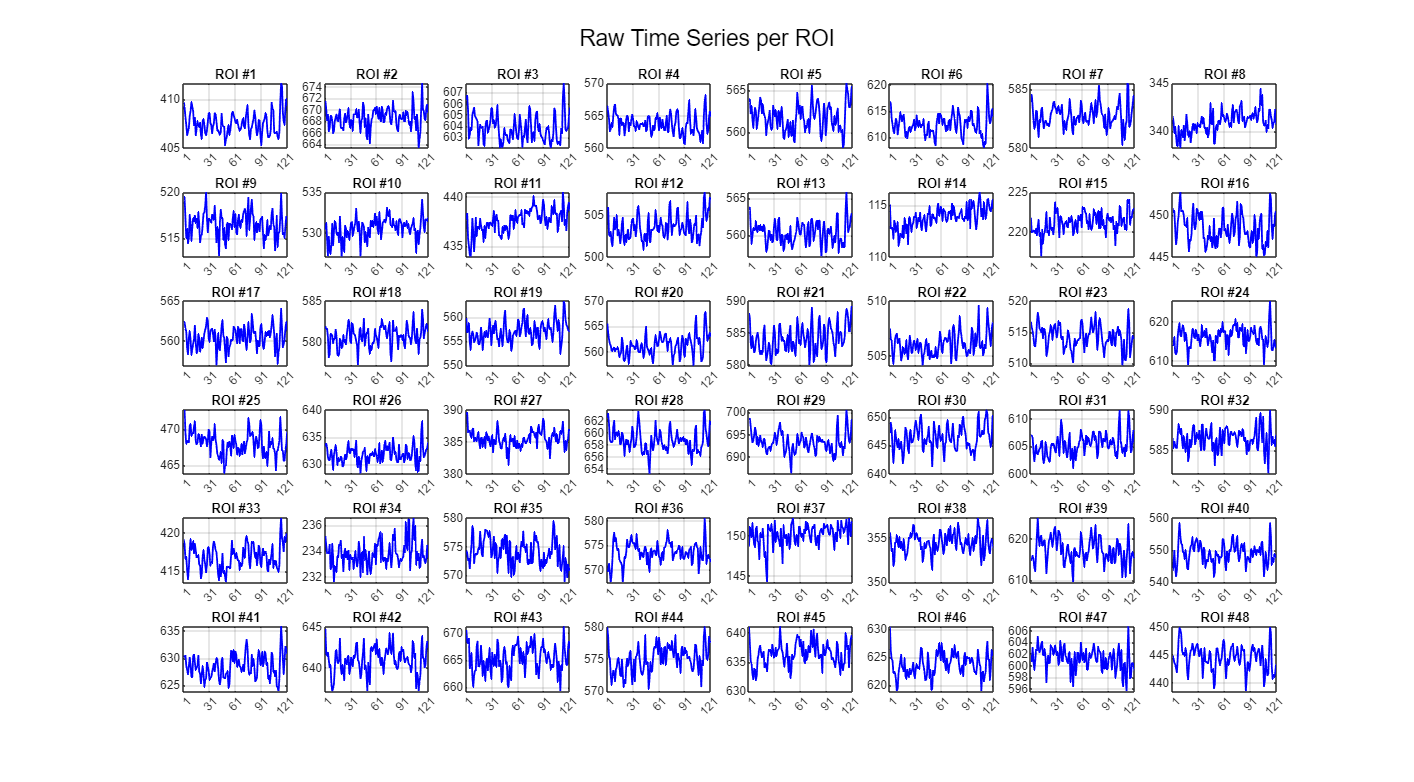

Raw Timeseries per ROI Saved in: D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step9_roi_timeseries_raw_byROI.png
          D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step9_roi_timeseries_raw_byROI.fig


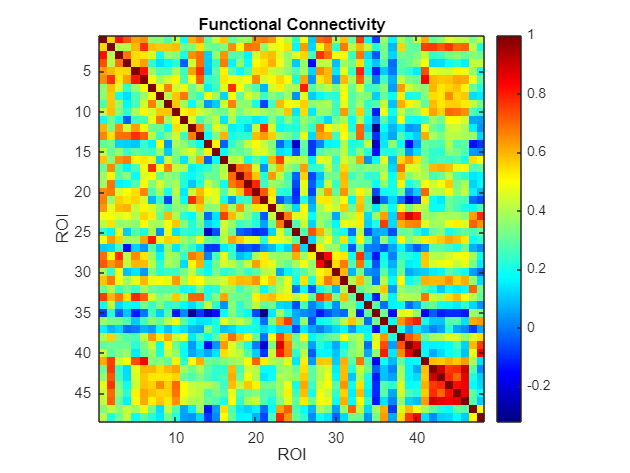

FC Matrix Saved in: D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step9_fc_matrix.png
          D:\UniGE\Research_Track\ds000224-download\sub-MSC03\ses-func01\func\memoryfaces\figures\step9_fc_matrix.fig


% === Step 9: ROI Time Series Extraction and Functional Connectivity (in MNI)

[roi_timeseries, roi_ts_z, fc_matrix, roi_labels] = ...
    analyze_timeseries_fc(warped_epi_path, ho_resliced_path, ...
                          'SaveFigures', true, ...
                          'SaveDir', fig_dir, ...
                          'FigurePrefix', 'step9');

% === Step 10: Create a table with the most correlated ROI according to a threshold
[roi_pair_table] = report_high_fc_pairs(fc_matrix, ho_resliced_path, base_path, 1.5, ...
    'SaveFigures', true, 'SaveTable', true, 'SaveDir', fig_dir, 'FigurePrefix', 'step10_');

% === Step 11: Overlaid ROI in MNI space of EPI and T1
%This step is just for visulaization (Quality Check) of correctly overlaid atlas and EPI-T1 images. They are not automatically saved
% 1) EPI underlay
overlay_ROIs_volshow(warped_epi_path, ho_resliced_path, 60);

% 2) T1 underlay
overlay_ROIs_volshow(rT1_on_wEPI, ho_resliced_path, 20);
